## Simulation of two stage rocket for SD2900

Simulates the trajectory of a two stage rocket, aimed for a specific altitude and orbital speed

% Prep for solver and so on
options = odeset;
mu = 398600;
V = [];
gam = [];
X = [];
H = [];
m = [];
tvec = [];
gvec = [];
Dvec = [];

H_star   = 819800;
% V_star   = sqrt(mu/(6371+819.8));
V_star = 7321;
Gam_star = 0;

g0 = 9.81;

t_burnoff1 = 0; % How much more or less time to simulate after fuel is burnt off for stage 1
t_burnoff2 = -60; % How much more or less time to simulate after fuel is burnt off for stage 2

## Data for Stage 2 

T2 = 890E3; % thrust [N]
isp2 = 369; % Specific impulse for stage 2
m_p2 = 86400; % Fuel mass
% m_p2 = 49.135E3;
m_s2 = 10E3; % Structural mass
m_sat = 4600; % Payload (satellite) mass
m_stage2 = m_s2 + m_p2 + m_sat; % Summation of stage 2 mass
m_o_2 = m_stage2; % Mass of rocket [kg]
m_f_2 = m_s2+m_sat; %Final mass of stage 2 + payload
B2 = T2./(isp2*g0); % Burn rate of fuel
t_burnout_2 = m_p2/B2; % Time to burn all fuel

## Data for Stage 1 + Stage 2 as payload

T1 = 6570E3; % thrust [N]
isp = 329; % Specific impulse for stage 1

m_p1 = 345600*1; % Propellant mass [kg]
% m_p1 = 242.19E3*0;
% m_s1 = 30900; % Structural mass [kg]
m_s1 = 30E3; % Structural mass [kg]
m_stage2 = m_sat + m_p2 + m_s2; % Payload mass [kg]
m_o = m_s1+m_p1+m_stage2; % Mass of rocket [kg]
m_f_1 = m_s1+m_stage2; % Final mass of rocket [kg]
B1 = T1./(isp*g0); % Burn rate of fuel [kg/s]
A = (3.5^2)*pi; % Cross sectional area m^2
t_burnout_1 = m_p1/B1; % Time to burn all fuel
t_straight = 5.649999999999999; % How long to go straight up (before tilting to induce gravity turn)
t_afterTurn = t_burnout_1-t_straight+t_burnoff1; % Time to burn after turning (based on how much burn time is left after having gone vertically)

#### Dethrottle scheme

dethrottle_K = 1; % Possibility to dethrottle if air drag is high, Don't use unless you're playing around!
dragLimit = -1;
% dethrottle_K,dragLimit;

## Straight part Stage 1

### Simulation

y0 = [0; pi/2; 0; 0; m_o]'; % Starting values for stage 1, straight part

tburn = [0 t_straight]; % Define start and end time
[t,U] = ode45(@(t,U) GT_fun_3(t,U,T1,B1,1,m_f_1,A,dethrottle_K,dragLimit,0,V_star),tburn,y0,options); % Numerical integration

%
%Saving output in separate vectors
V = [V U(:,1)];
gam = [gam; U(:,2)];
X = [X; U(:,3)];
H = [H; U(:,4)];
m = [m; U(:,5)];
tvec = [tvec; t];
turnI = length(V); %Save index at stage 1 end
%

## Turning part Stage 1

### Simulation

tburn = [0 t_afterTurn]; % Burn time for the rocket (start and end [s])
y0 = [U(end,1) U(end,2)*0.999 U(end,3) U(end,4) U(end,5)]; % Initial values for the solver
[t,U] = ode45(@(t,U) GT_fun_3(t,U,T1,B1,0,m_f_1,A,dethrottle_K,dragLimit,0,V_star),tburn,y0,options); % Numerical integration

%
%Saving output in separate vectors
V = [V; U(:,1)]; 
gam = [gam; U(:,2)];
X = [X; U(:,3)];
H = [H; U(:,4)];
m = [m; U(:,5)];
tvec = [tvec; t+tvec(end)];
%

## Stage 2 First burn

A = (3.5^2)*pi; % Cross sectional area m^2
stagingI21 = length(V); % Save index
tburn = [0 t_burnout_2+t_burnoff2]; % Burn time for the rocket (start and end [s])

### Simulation

y0 = [U(end,1) U(end,2) U(end,3) U(end,4) m_o_2]; % Initial values for the solver
[t,U] = ode45(@(t,U) GT_fun_3(t,U,T2,B2,0,m_f_2,A,dethrottle_K,dragLimit,0,V_star),tburn,y0,options); % Numerical integration

%
%Saving output in separate vectors
V = [V; U(:,1)]; 
gam = [gam; U(:,2)];
X = [X; U(:,3)];
H = [H; U(:,4)];
m = [m; U(:,5)];
tvec = [tvec; t+tvec(end)];
%

## Stage 2 Stabilizing burn

A = (3.5^2)*pi; % Cross sectional area m^2
stabI = length(V);
tburn = [0 500]; % Burn time for the rocket (start and end [s])
dethrottle_K =1; % Don't use!

### Simulation

y0 = [U(end,1) U(end,2) U(end,3) U(end,4) U(end,5)]; % Initial values for the solver
[t,U] = ode45(@(t,U) GT_fun_3(t,U,T2,B2,0,m_f_2,A,dethrottle_K,dragLimit,1,V_star),tburn,y0,options); % NUmerical integration

%
%Saving output in separate vectors
V = [V; U(:,1)]; 
gam = [gam; U(:,2)];
X = [X; U(:,3)];
H = [H; U(:,4)];
m = [m; U(:,5)];
tvec = [tvec; t+tvec(end)];
%

## Plotting figures

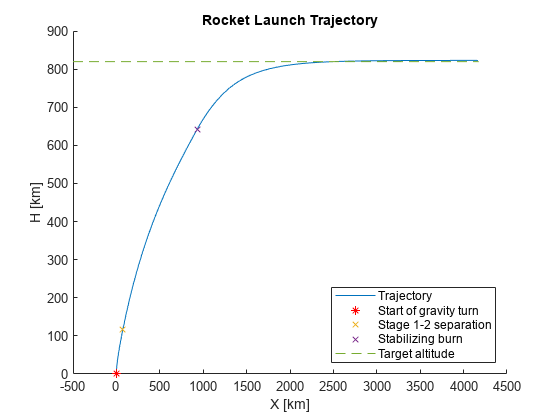

figure
hold on
plot(1E-3*X,1E-3*H) % Trajectory
scatter(1E-3*X(turnI),1E-3*H(turnI),'*','red') % Start of turn
scatter(1E-3*X(stagingI21),1E-3*H(stagingI21),'x') % Staging 1-2
scatter(1E-3*X(stabI),1E-3*H(stabI),'x') % Start of stabilizing burn
title('Rocket Launch Trajectory')
xlabel('X [km]')
ylabel('H [km]')
plot([-500 1E-3*X(end)+10],1E-3*H_star*[1 1],'--') % Target height
legend({'Trajectory','Start of gravity turn','Stage 1-2 separation','Stabilizing burn','Target altitude'},'Location','southeast')

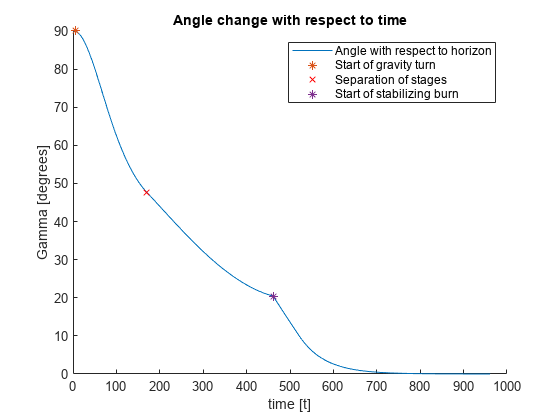

figure
hold on
plot(tvec,rad2deg(gam))
scatter(tvec(turnI),rad2deg(gam(turnI)),'*')
scatter(tvec(stagingI21),rad2deg(gam(stagingI21)),'x','red')
scatter(tvec(stabI),rad2deg(gam(stabI)),'*') % Start of stabilizing burn
title('Angle change with respect to time')
xlabel('time [t]')
ylabel('Gamma [degrees]')
legend({'Angle with respect to horizon','Start of gravity turn','Separation of stages','Start of stabilizing burn'},'Location','northeast')

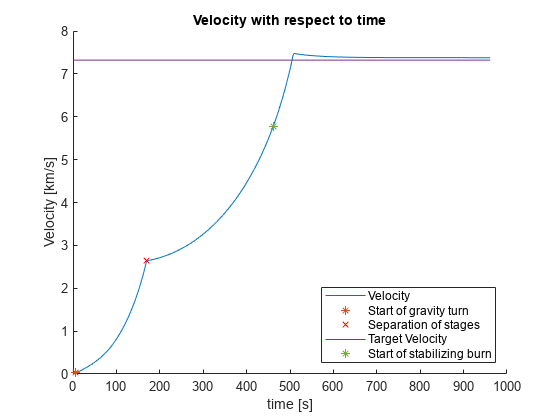

figure
hold on
plot(tvec,1E-3*V) % Velocity 
scatter(tvec(turnI),1E-3*V(turnI),'*') % Start of gravity turn
scatter(tvec(stagingI21),1E-3*V(stagingI21),'x','red') % Separation of stages
plot([0 tvec(end)], 1E-3*[V_star V_star]) % Target Velocity
scatter(tvec(stabI),1E-3*V(stabI),'*') % Start of stabilizing burn
title('Velocity with respect to time')
xlabel('time [s]')
ylabel('Velocity [km/s]')
legend({'Velocity','Start of gravity turn','Separation of stages','Target Velocity','Start of stabilizing burn'},'Location','southeast')

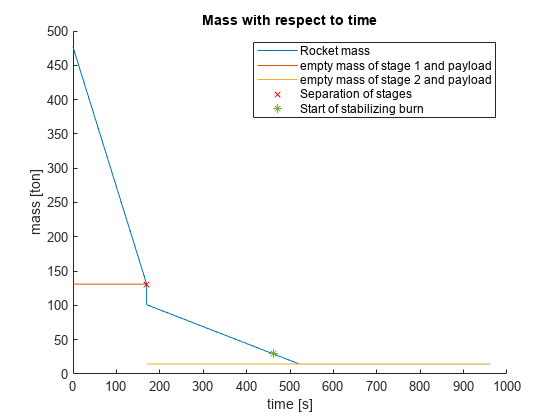

figure
hold on
plot(tvec,m*1E-3) % Mass of rocket (scaled to tons
plot([0 t_straight+t_afterTurn], 1E-3*[m_f_1 m_f_1]) % Empty mass of stage 2+ payload
plot([t_straight+t_afterTurn tvec(end)],1E-3*[m_f_2 m_f_2]) % empty mass of stage 2 and payload
scatter(tvec(stagingI21),1E-3*m(stagingI21),'x','red') % Separation of stages
scatter(tvec(stabI),1E-3*m(stabI),'*') % Start of stabilizng burn
title('Mass with respect to time')
xlabel('time [s]')
ylabel('mass [ton]')
legend({'Rocket mass', 'empty mass of stage 1 and payload','empty mass of stage 2 and payload' ,'Separation of stages','Start of stabilizing burn'},'Location','northeast')

%% LOTS OF OTHER CALCULATIONS THAT I HAVE DISCARDED
% Mostly estimations of drag

% [~,~,~,rho_vec] = atmosisa(H);
% above20k = H<20000;
% rho_vec = rho_vec.*above20k;
% R_M = 6371;
% Gvec = g0.*(R_M./(R_M+H)).^2; % Calc of gravity at radius m/s^2];
% timestep = [tvec' 0]-[0 tvec'];
% timestep = timestep(1:end-1);
% sum(sum(Gvec.*timestep))
% mean(Gvec)*tvec(end)
% C_d = 0.237;
% Dvec = 0.5.*rho_vec.*A.*C_d.*V.^2; % Aerodynamic drag
% % sum(sum(Dvec.*timestep))
% % sum(sum(Dvec./m))
% sum(timestep.*(Dvec./m));
% figure
% plot(H,rho_vec)
% figure
% hold on 
% % subplot(1,2,1)
% plot(tvec,Dvec/m)

% % plot(tvec,V)
% % subplot(1,2,2)
% % plot(tvec,Gvec)

Save Figures